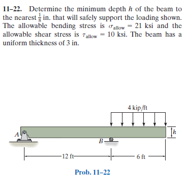

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-22P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-11-problem-22P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

H_min = default_struct('bending', 'shear', 'limit');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 12*u.ft, [false true]);
b = b.add('distributed', 'force', -4*u.kip/u.ft, [12 18]*u.ft);
b.L = 18*u.ft;

# section properties

B = 3*u.in;
H = sym('H', 'positive');
b.I(H) = rewrite(B*H^3/12, u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{48\,x\,\left(x-12\,\mathrm{ft}\right)\,\left(x+12\,\mathrm{ft}\right)}{\text{E}\,H^{3}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 12\,\mathrm{ft}\\ -\frac{8\,\left(x-12\,\mathrm{ft}\right)\,\left(x^{3}-60\,x^{2}\,\mathrm{ft}+1224\,x\,{\mathrm{ft}}^{2}-6048\,{\mathrm{ft}}^{3}\right)}{\text{E}\,H^{3}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{144\,\left(48\,{\mathrm{ft}}^{2}-x^{2}\right)}{\text{E}\,H^{3}}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }x\leq 12\,\mathrm{ft}\\ -\frac{32\,\left(x^{3}-54\,x^{2}\,\mathrm{ft}+972\,x\,{\mathrm{ft}}^{2}-5184\,{\mathrm{ft}}^{3}\right)}{\text{E}\,H^{3}}\,\frac{\mathrm{kip}}{{\mathrm{ft}}^{2}} & \text{ if }12\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -6\,x\,\mathrm{kip} & \text{ if }x<12\,\mathrm{ft}\\ -2\,{\left(x-18\,\mathrm{ft}\right)}^{2}\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}\leq x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -6\,\mathrm{kip} & \text{ if }x<12\,\mathrm{ft}\\ -4\,\left(x-18\,\mathrm{ft}\right)\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}\leq x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<12\,\mathrm{ft}\\ -4\,\frac{\mathrm{kip}}{\mathrm{ft}} & \text{ if }12\,\mathrm{ft}\leq x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & -6\,\mathrm{kip}\\ \mathrm{Rb} & 30\,\mathrm{kip} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

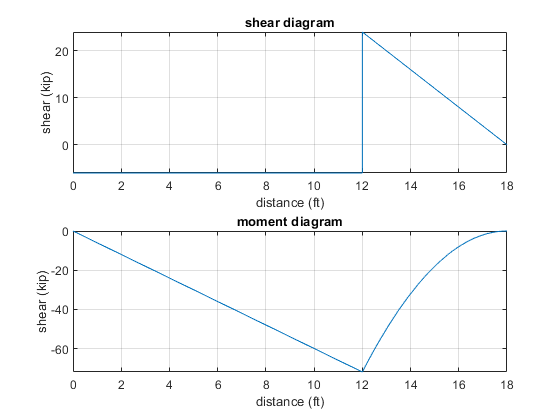

beam.shear_moment(m, v, [0 b.L], {'kip' 'ft'});

# maximum loads

M_max = -m(12*u.ft)

$$M\_max = 72\,\mathrm{ft}\,\mathrm{kip}$$

V_max = v(12*u.ft)

$$V\_max = 24\,\mathrm{kip}$$

# minimum beam height based on bending

sigma_allow = 21*u.ksi;
C(H) = H/2;
b.I = rewrite(b.I, u.in);
sigma_max = rewrite(M_max*C/b.I, [u.ksi u.in])

$$sigma\_max(H) = \frac{1728}{H^{2}}\,{\mathrm{in}}^{2}\,\mathrm{ksi}$$

H_min.bending = solve(sigma_max == sigma_allow);
H_min_bending = vpa(H_min.bending, 3) %#ok<NASGU> 

$$H\_min\_bending = 9.07\,\mathrm{in}$$

# minimum beam height based on shear

tau_allow = 10*u.ksi;
Q_max(H) = (H/4)*(B*H/2);
t_min = B;
tau_max = rewrite(V_max*Q_max/(b.I*t_min), [u.ksi u.in])

$$tau\_max(H) = \frac{12}{H}\,\mathrm{in}\,\mathrm{ksi}$$

H_min.shear = solve(tau_max == tau_allow);
H_min_shear = vpa(H_min.shear) %#ok<NASGU> 

$$H\_min\_shear = 1.2\,\mathrm{in}$$

# limit beam height

H_min_vals = [H_min.bending; H_min.shear];
loc = isAlways(sigma_max(H_min_vals) <= sigma_allow & ...
               tau_max(H_min_vals) <= tau_allow);
H_min.limit = H_min_vals(loc);
H_min_limit = vpa(H_min.limit, 3) %#ok<NASGU> 

$$H\_min\_limit = 9.07\,\mathrm{in}$$

# clean up

addvar(y);
setassum(old_assum, 'Mode', 'clear');
clear old_assum;
clear H_min_bending;
clear H_min_shear;
clear H_min_vals loc H_min_limit;